%A. Loading the data for the 'oblong TPU' and 'oblong rubber'
Oblong_TPU = load('/Users/tamamabibi/Library/CloudStorage/OneDrive-ImperialCollegeLondon/Computer Vision and Pattern Recognition/PR_CW_mat/oblong_TPU_papillarray_single.mat');
Oblong_Rub = load('/Users/tamamabibi/Library/CloudStorage/OneDrive-ImperialCollegeLondon/Computer Vision and Pattern Recognition/PR_CW_mat/oblong_rubber_papillarray_single.mat');
%Extract the displacement from the data
Oblong_TPU_displacement = Oblong_TPU.sensor_matrices_displacement;
Oblong_Rub_displacement = Oblong_Rub.sensor_matrices_displacement;

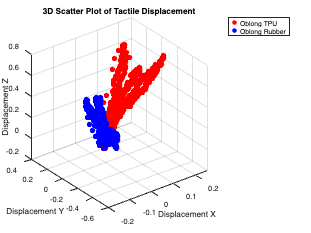

%B. Visualise the displacement from the data using a 3D scatter plot
% Extract X, Y, Z displacement components for both objects
D_X_TPU = Oblong_TPU_displacement(:, 1); % Replace with appropriate indexing
D_Y_TPU = Oblong_TPU_displacement(:, 2);
D_Z_TPU = Oblong_TPU_displacement(:, 3);

D_X_Rub = Oblong_Rub_displacement(:, 1); % Replace with appropriate indexing
D_Y_Rub = Oblong_Rub_displacement(:, 2);
D_Z_Rub = Oblong_Rub_displacement(:, 3);

% Create a 3D scatter plot
figure;
scatter3(D_X_TPU, D_Y_TPU, D_Z_TPU, 50, 'r', 'filled'); % Oblong TPU in red
hold on;
scatter3(D_X_Rub, D_Y_Rub, D_Z_Rub, 50, 'b', 'filled'); % Oblong Rubber in blue

% Customize plot
xlabel('Displacement X');
ylabel('Displacement Y');
zlabel('Displacement Z');
title('3D Scatter Plot of Tactile Displacement');
legend('Oblong TPU', 'Oblong Rubber');
grid on;
hold off;

Observations of the 3D plot

**Class separation:**

Oblong TPU - more spread out along the positive z-axis and both positive/negative Y-axis.

Oblong rubber - more Compact and closed in

**Range of Displacement**:

The TPU (red) displays a larger range in the Z-axis and Y-axis compared to the Rubber (blue), indicating that the TPU material exhibits a broader displacement spectrum.

The Rubber (blue) has a more compact distribution in 3D space.

**Directionality**:

The TPU seems to have a directional bias in its displacement pattern, with displacements extending more along certain axes.

The Rubber displacement points are concentrated around a smaller region, implying less variation and perhaps higher stiffness or resistance to deformation.

**Material Behavior**:

The spread and clustering differences likely reflect material properties such as flexibility, elasticity, or resistance to deformation under tactile forces.

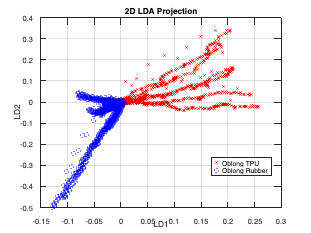

% C. Applying The LDA
%Combining Displacement data
features_tpu = reshape(Oblong_TPU_displacement, size(Oblong_TPU_displacement,1),[]);
features_rub = reshape(Oblong_Rub_displacement, size(Oblong_Rub_displacement,1),[]);
% Create labels
labels_tpu = zeros(size(features_tpu, 1),1); %Class 0 for TPU
labels_rub = ones(size(features_rub, 1),1); %Class 1 for Rubber

% Combine data and labels
features = [features_tpu; features_rub];
labels = [labels_tpu; labels_rub];

% Train LDA model
lda_model = fitcdiscr(features, labels);

% Project data onto LDA space
lda_transformed = lda_model.X;

% Visualize in 2D
figure;
gscatter(lda_transformed(:,1), lda_transformed(:,2), labels, 'rb', 'xo');
xlabel('LD1');
ylabel('LD2');
title('2D LDA Projection');
legend('Oblong TPU', 'Oblong Rubber');
grid on;

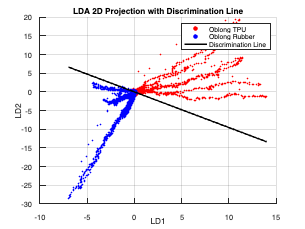

% D. Applying the LDA to the 3D displacement data
% Reducing the data to 2 Dimensions and Re-plot

% Combine all displacement data for TPU and Rubber
displacement_data = [Oblong_TPU_displacement; Oblong_Rub_displacement];

% Create class labels (0 = TPU, 1 = Rubber)
labels = [zeros(size(Oblong_TPU_displacement, 1), 1); ones(size(Oblong_Rub_displacement, 1), 1)];

% Apply LDA
lda_model = fitcdiscr(displacement_data, labels);

% Project data into 2D space
lda_2d = lda_model.X .* lda_model.Coeffs(1,2).Linear';

% Extract class-wise projections
lda_tpu = lda_2d(labels == 0, :);
lda_rub = lda_2d(labels == 1, :);

% Plot the 2D LDA result
figure;
scatter(lda_tpu(:,1), lda_tpu(:,2), 5, 'r', 'filled'); % Oblong TPU in red
hold on;
scatter(lda_rub(:,1), lda_rub(:,2), 5, 'b', 'filled'); % Oblong Rubber in blue

% Plot the discrimination line
coeff = lda_model.Coeffs(1,2).Linear;
k = -coeff(1)/coeff(2); % Slope
x_range = linspace(min(lda_2d(:,1)), max(lda_2d(:,1)), 100);
y_range = k * x_range; % Line equation
plot(x_range, y_range, 'k', 'LineWidth', 2); % Black discrimination line

xlabel('LD1');
ylabel('LD2');
title('LDA 2D Projection with Discrimination Line');
legend('Oblong TPU', 'Oblong Rubber', 'Discrimination Line');
grid on;
hold off;

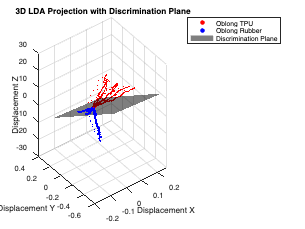

% 3D plot with discrimination plane
% Extract 3D displacement data
D_X = displacement_data(:,1);
D_Y = displacement_data(:,2);
D_Z = displacement_data(:,3);

% Plot the 3D displacement points
figure;
scatter3(D_X(labels == 0), D_Y(labels == 0), D_Z(labels == 0), 5, 'r', 'filled'); % TPU
hold on;
scatter3(D_X(labels == 1), D_Y(labels == 1), D_Z(labels == 1), 5, 'b', 'filled'); % Rubber

% Plot the discrimination plane
% Use coefficients of the LDA model
plane_coeff = lda_model.Coeffs(1,2).Linear; % [a, b, c] for ax + by + cz = d
a = plane_coeff(1);
b = plane_coeff(2);
c = plane_coeff(3);
d = lda_model.Coeffs(1,2).Const; % Plane offset

% Define the range for the plane
[x_plane, y_plane] = meshgrid(linspace(min(D_X), max(D_X), 30), linspace(min(D_Y), max(D_Y), 30));
z_plane = -(a*x_plane + b*y_plane + d)/c;

% Plot the plane
surf(x_plane, y_plane, z_plane, 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'FaceColor', 'k');

% Customize the plot
xlabel('Displacement X');
ylabel('Displacement Y');
zlabel('Displacement Z');
title('3D LDA Projection with Discrimination Plane');
legend('Oblong TPU', 'Oblong Rubber', 'Discrimination Plane');
grid on;
hold off;

E) different outcomes

**Observations**

- **3D LDA with Discrimination Plane**:

- The 3D projection highlights the separation between the two classes (Oblong TPU and Oblong Rubber) with a discrimination plane.

- The plane effectively separates the classes in the higher-dimensional space, capturing the significant variance and maximizing class separation.

- **2D LDA Projection**:

- The dimensionality reduction to 2D provides a simplified visualization, projecting the data onto two linear discriminants (LD1 and LD2).

- Class separation is evident, but overlapping regions exist due to some loss of spatial information from the dimensionality reduction.

- **2D LDA with Discrimination Line**:

- The discrimination line clearly distinguishes between the two classes based on their projections onto LD1 and LD2.

- While the line separates the classes, there are areas where the data points are misclassified or lie close to the boundary.

**Physical Properties and Sensor Influence**

- **Oblong TPU vs. Oblong Rubber**:

- **Material Compliance**: TPU is more elastic and flexible than rubber, which could cause greater variations in the tactile displacement measurements. This might lead to more dispersed data points in the feature space.

- **Surface Texture**: Rubber may have a rougher texture compared to TPU, causing a consistent interaction with the sensor, which can result in more tightly clustered points.

- **Force Absorption**: TPU absorbs more force and deforms significantly under pressure, introducing additional nonlinearity to the data compared to rubber.

- These differences likely contribute to the variability in sensor readings, affecting the class separation.

- **Sensor Sensitivity**:

- The tactile sensor's response is likely more sensitive to small deformations caused by TPU, which could result in larger scatter for the TPU class.

- Variations in the mechanical properties of the objects may affect the data density and overlap observed in the 2D projection.